*Copyright 2025 The MathWorks, Inc.*

# **EXERCISE 2 : 5G** **Intercell Interference Modeling**

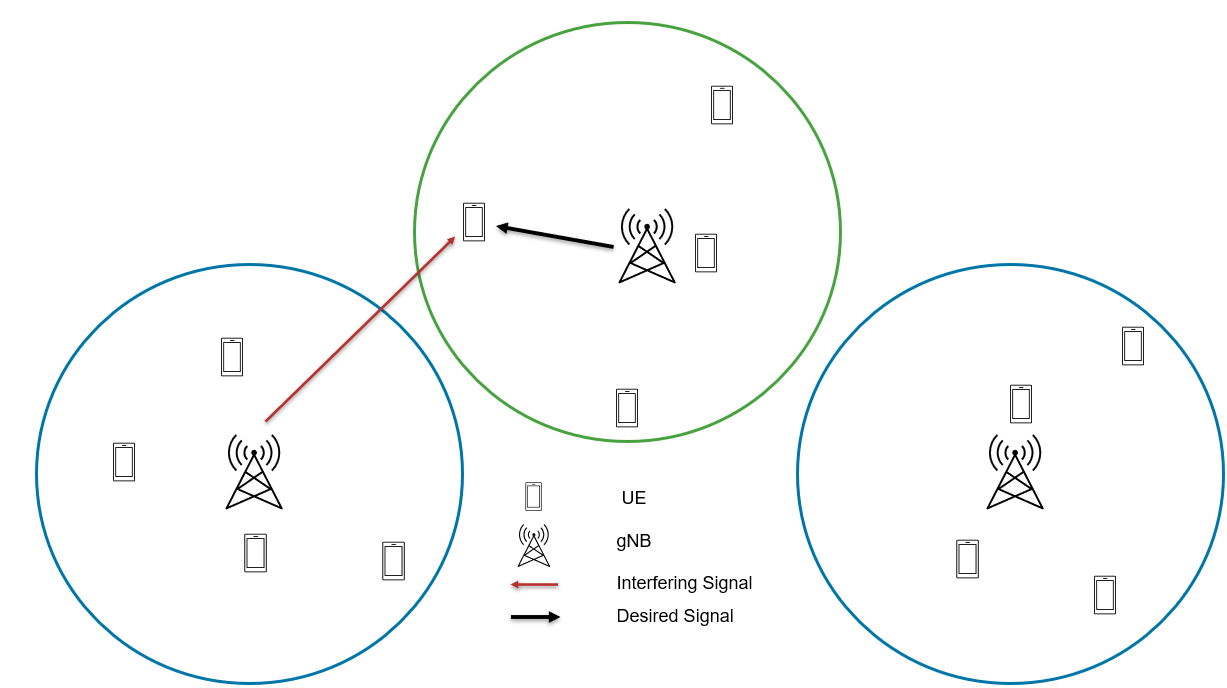

This exercise shows how to simulate a multi cell interference scenario and measure the impact on network performance due to downlink (DL) intercell interference caused by nearby cells. The goals are:

- Model a multi-cell network scenario

- Analyze the impact on user throughput, particularly for users near the cell edge

- Visualize how channel conditions change as a result of inter-cell interference                            

#### Close any previously opened figures and add the path to the helpers and utilities directories 

- Close all previous windows

- Add path to helpers and utilities

- Reset the random number generator for reproducibility

all_figs = findall(0, 'type', 'figure');close(all_figs); 
p = addpath(fullfile('.', 'Shared', 'Helpers'), fullfile('.', 'Shared', 'Utilities')); 
rng("default")  

#### Initialize Variables and Wireless Network Simulator

- Set Radius of each cell (in meters)

- Initialize the Wireless Network Simulator

- Number of frames to simulate and simulation time in seconds 

- Launch the wireless network viewer to visualize the network during simulation

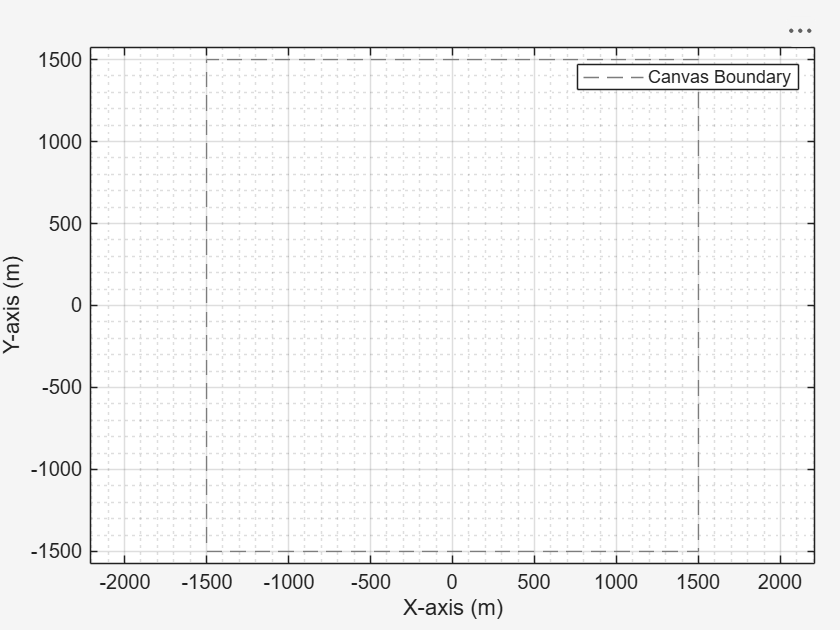

numUEsPerCell = 4;
cellRadius = 500;
numFrameSimulation = 10;
simulationTime = numFrameSimulation*1e-2;
networkSimulator = wirelessNetworkSimulator.init;
viewerObj = wirelessNetworkViewer(CanvasSize=[3000 3000]);

# Task 1/4: Create three 5G base stations 

**Description of the task**

Model a 5G base station by configuring the physical and MAC layer parameters and specifying its position [x,y,z] in Cartesian coordinates (meters).

- Support both SISO and MIMO antenna configurations as per 3GPP specifications 

- Configure subcarrier spacing (SCS), up to: 120 kHz 

- Configure channel bandwidth, up to: 400 MHz

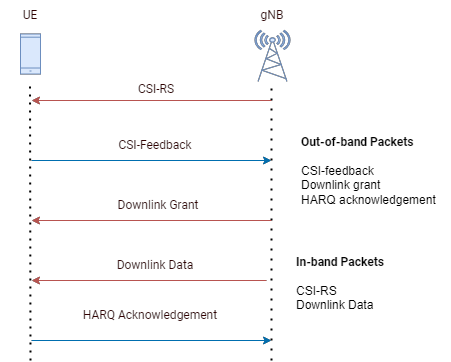

**DL Transmission**

Downlink (DL) transmission workflow:

- The gNB (Next Generation Node B) sends CSI-RS (Channel State Information Reference Signals) for channel estimation 

- The UE (User Equipment) estimates the channel and reports CSI (Channel State Information) feedback: 

- PMI (Precoding Matrix Indicator)

- RI (Rank Indicator)

- CQI (Channel Quality Indicator)

- The gNB uses this feedback to schedule DL transmission (modulation and coding scheme, number of layers, etc.) 

- DL data is transmitted to the UE 

- The UE sends a HARQ (Hybrid Automatic Repeat Request) acknowledgment (ACK/NACK) based on reception

**Instructions to complete the task**

Use` nrGNB() `function to create a NR base station 

Store NR base station in a variable named "gNB"

Hint:type `doc nrGBN`  in command window and see the "Syntax" section.

Note : use the following values as arguments 

-  Position=gNBPositions

-  Name=gNBNames

-  CarrierFrequency=carrierFrequency

numCells = 3;
gNBPositions = [0 0 30; 750 433 30; 750 -433 30];
gNBNames = ["gnb-1","gnb-2","gnb-3"];
carrierFrequency = 2.5e9;

% <Enter your code below>
gNBs = nrGNB(CarrierFrequency=carrierFrequency, ...
        Name=gNBNames, ...
        Position=gNBPositions);

#### Visualize the 5G base stations in the Network Viewer and add them as nodes to the network simulator

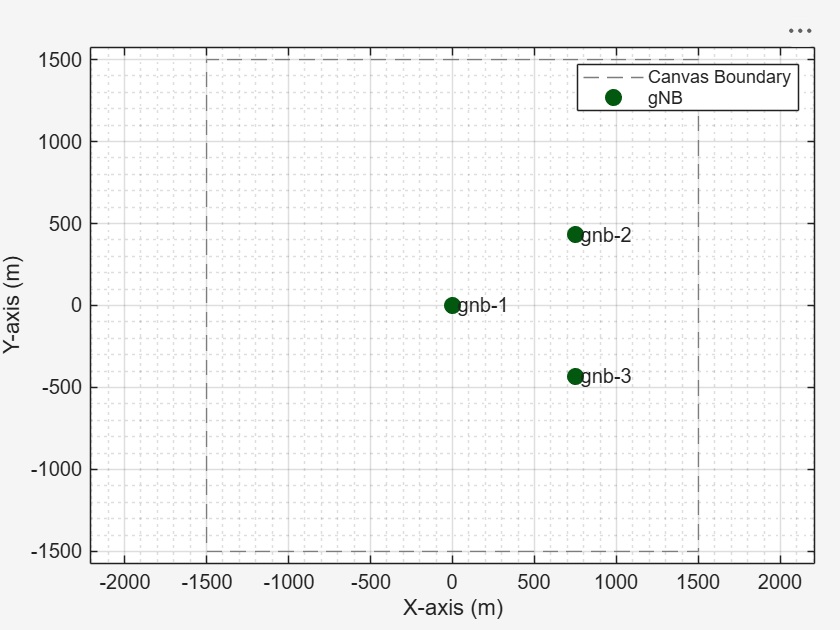

addNodes(networkSimulator,gNBs);
addNodes(viewerObj,gNBs,Type="gNB");

# Task 2/4: Create a NR user equipment for first cell

**Description of the task**

Model a 5G user equipment (UE) by configuring the physical and MAC layer parameters and specifying its position [x,y,z] in Cartesian coordinates (meters).

- Support both SISO and MIMO antenna configurations (up to 4 antennas) 

- Use the same physical (PHY) layer abstraction method as the gNB

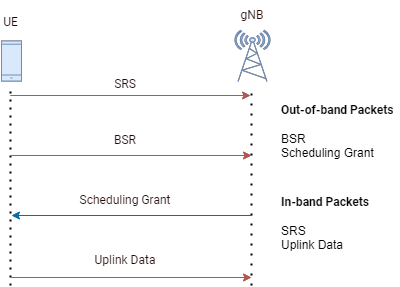

Uplink (UL) transmission workflow:

- UE sends SRS (Sounding Reference Signals) for channel estimation 

- gNB estimates UL CSI and determines parameters (TPMI, RI, MCS) 

- UE sends BSR (Buffer Status Report) to indicate data to transmit 

- gNB provides a scheduling grant

- UE transmits UL data over PUSCH (Physical Uplink Shared Channel)

**Instructions to complete the task**

Use `nrUE()` function to create a 5G user equipment (UE) 

Store NR base station in a variable named "UE"

Hint: type `doc nrUE` in command line, and see the "Syntax" section.

Note : use the following values as arguments 

- `Position=uePositions`

- `Name= ueNames`

uePositions = generateUEPositions(cellRadius,gNBPositions(1,:),numUEsPerCell);
ueNames = "ue-" + (1:size(uePositions,1));

% <Enter your code below>
UEs = nrUE(Position=uePositions,Name=ueNames);

# Task 3/4: Create the 5G network   

**Description of the task**

Connect UE(s) to the gNB and full buffer downlink traffic 

A note on full-buffer traffic

- Transmitter always has data to send (buffer never empty) 

- MAC queue is always full 

- Performance depends on network capacity 

- Used to measure maximum throughput 

- Helps study interference and scheduling 

- Common in 5G and WLAN simulations

**Instructions to complete the task**

Use connectUE() function to connect gNB to corresponding UEs

Hint: type `doc connectUE`, and see the "Syntax" section.

Note : use the following values as arguments 

- gNB

- UE

- FullBufferTraffic="DL"

% <Enter your code below>
connectUE(gNBs(1),UEs,FullBufferTraffic="DL");

**Visualize the first cell in the Network Viewer and add UEs to the network simulator**

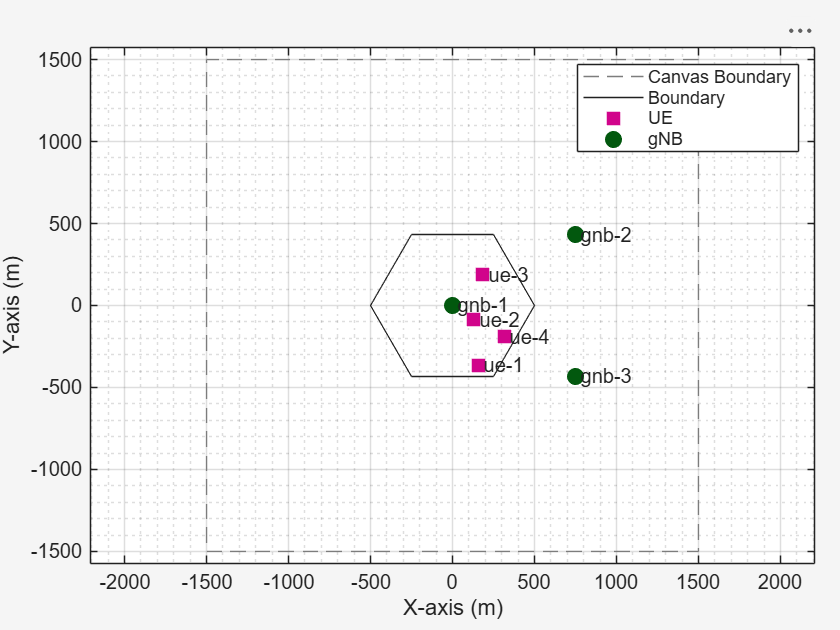

addNodes(networkSimulator,UEs)
addNodes(viewerObj,UEs,Type="UE");
showBoundary(viewerObj,Position=gNBPositions(1,:), BoundaryShape="Hexagon",Bounds=cellRadius, Name="Cell-1")

#### **Generate UE positions and UE names for Cell 2**

uePositions = generateUEPositions(cellRadius,gNBPositions(2,:),numUEsPerCell);
ueNames = "ue-" + (1:size(uePositions,1));

**Create and connect UEs to the corresponding gNB and configure full-buffer traffic in the downlink direction**

UEs = nrUE(Name=ueNames,Position=uePositions);
connectUE(gNBs(2),UEs,FullBufferTraffic="DL");

**Visualize the 2nd cell in the Network Viewer and add UEs to the network simulator**

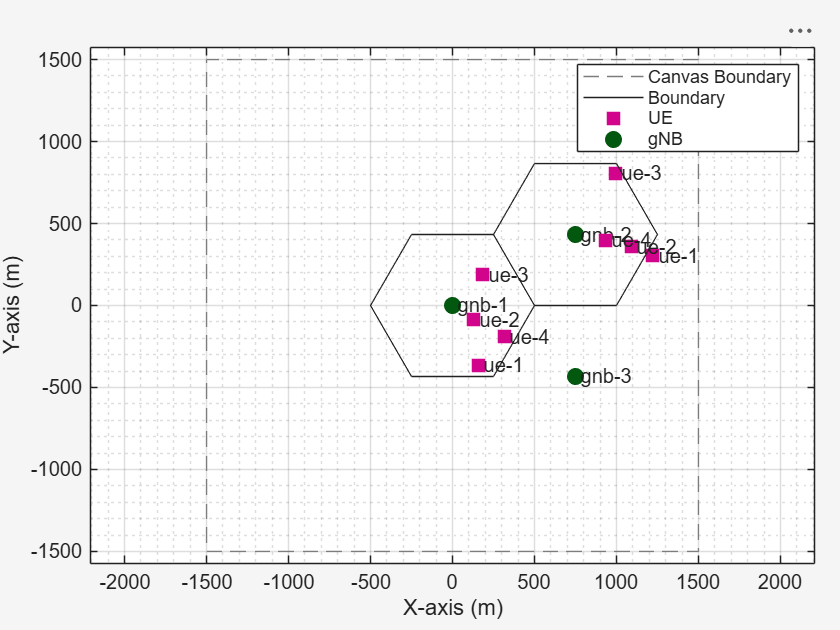

addNodes(networkSimulator,UEs)
addNodes(viewerObj,UEs,Type="UE");
showBoundary(viewerObj,Position=gNBPositions(2,:), BoundaryShape="Hexagon",Bounds=cellRadius, Name="Cell-2")

**Position the UEs within the cell of interest**

You can choose any of the three cells as the cell of interest for interference analysis. In this case, we select Cell 3.

Select random position of UEs in cell three 

cellofInterest = 3;
uePositions = generateUEPositions(cellRadius,gNBPositions(cellofInterest,:),numUEsPerCell);

Place UEs in particular region cell-3  

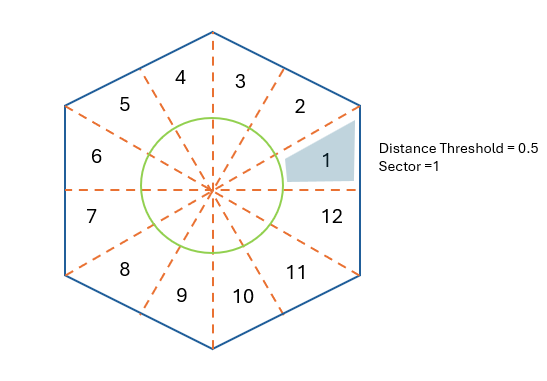

controlUEPositions = false;
if controlUEPositions
    distanceThreshold = 1; % fraction of cell radius
    sector =  1; % 1 to 8, represents a sector of 45 degrees
    uePositions = generateUEPositions(cellRadius,gNBPositions(cellofInterest,:),numUEsPerCell,distanceThreshold,sector);
end

Generate the UE names for Cell 3

ueNames = "ue-" + (1:size(uePositions,1));

- Create and connect UEs to the corresponding gNB and configure full-buffer traffic in the downlink direction

- Visualize the 2nd cell in the Network Viewer and add UEs to the network simulator

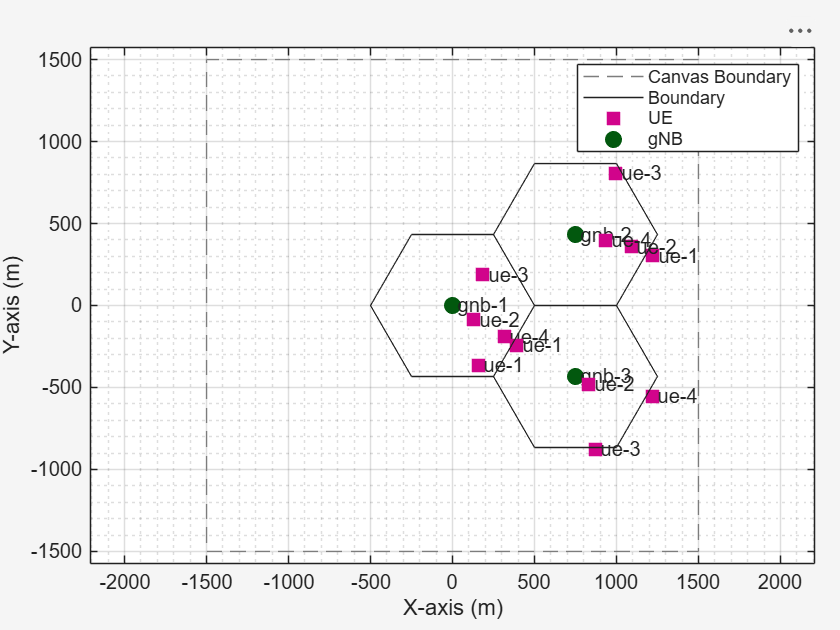

UEs = nrUE(Name=ueNames,Position=uePositions);
connectUE(gNBs(cellofInterest),UEs,FullBufferTraffic="DL");
addNodes(networkSimulator,UEs)
addNodes(viewerObj,UEs,Type="UE");
showBoundary(viewerObj,Position=gNBPositions(3,:), BoundaryShape="Hexagon",Bounds=cellRadius, Name="Cell-3")

#### Add channel Model 

- The default channel model is Free Space Path Loss (FSPL).

- You can use prebuilt channel models for various deployment scenarios defined in 3GPP TR 38.901.

- Control whether small-scale fading is applied to interfering signals in the channel model.

- You also use custom channel models 

fspl = false;
if ~fspl
channel = h38901Channel(Scenario="UMa");
addChannelModel(networkSimulator,@channel.channelFunction);
connectNodes(channel,networkSimulator,InterfererHasSmallScale=true);
end

#### Enable visualizations

The displayed visualizations and metrics correspond to the selected cell of interest.

- Cell Performance Metrics – Shows key KPIs like throughput, fairness, and buffer status 

- RLC Metrics – Displays data transmitted at the RLC layer for each UE 

- BLER Metrics – Visualizes block error rates in uplink and downlink 

- Resource Grid Allocation – Shows time-frequency resource allocation and HARQ activity 

- Channel Quality – Displays MCS variations across time and frequency 

- Simulation Summary – Compares achieved performance with theoretical limits

simSchedulingLogger = helperNRSchedulingLogger(numFrameSimulation, gNBs(cellofInterest),UEs,LinkDirection="DL");

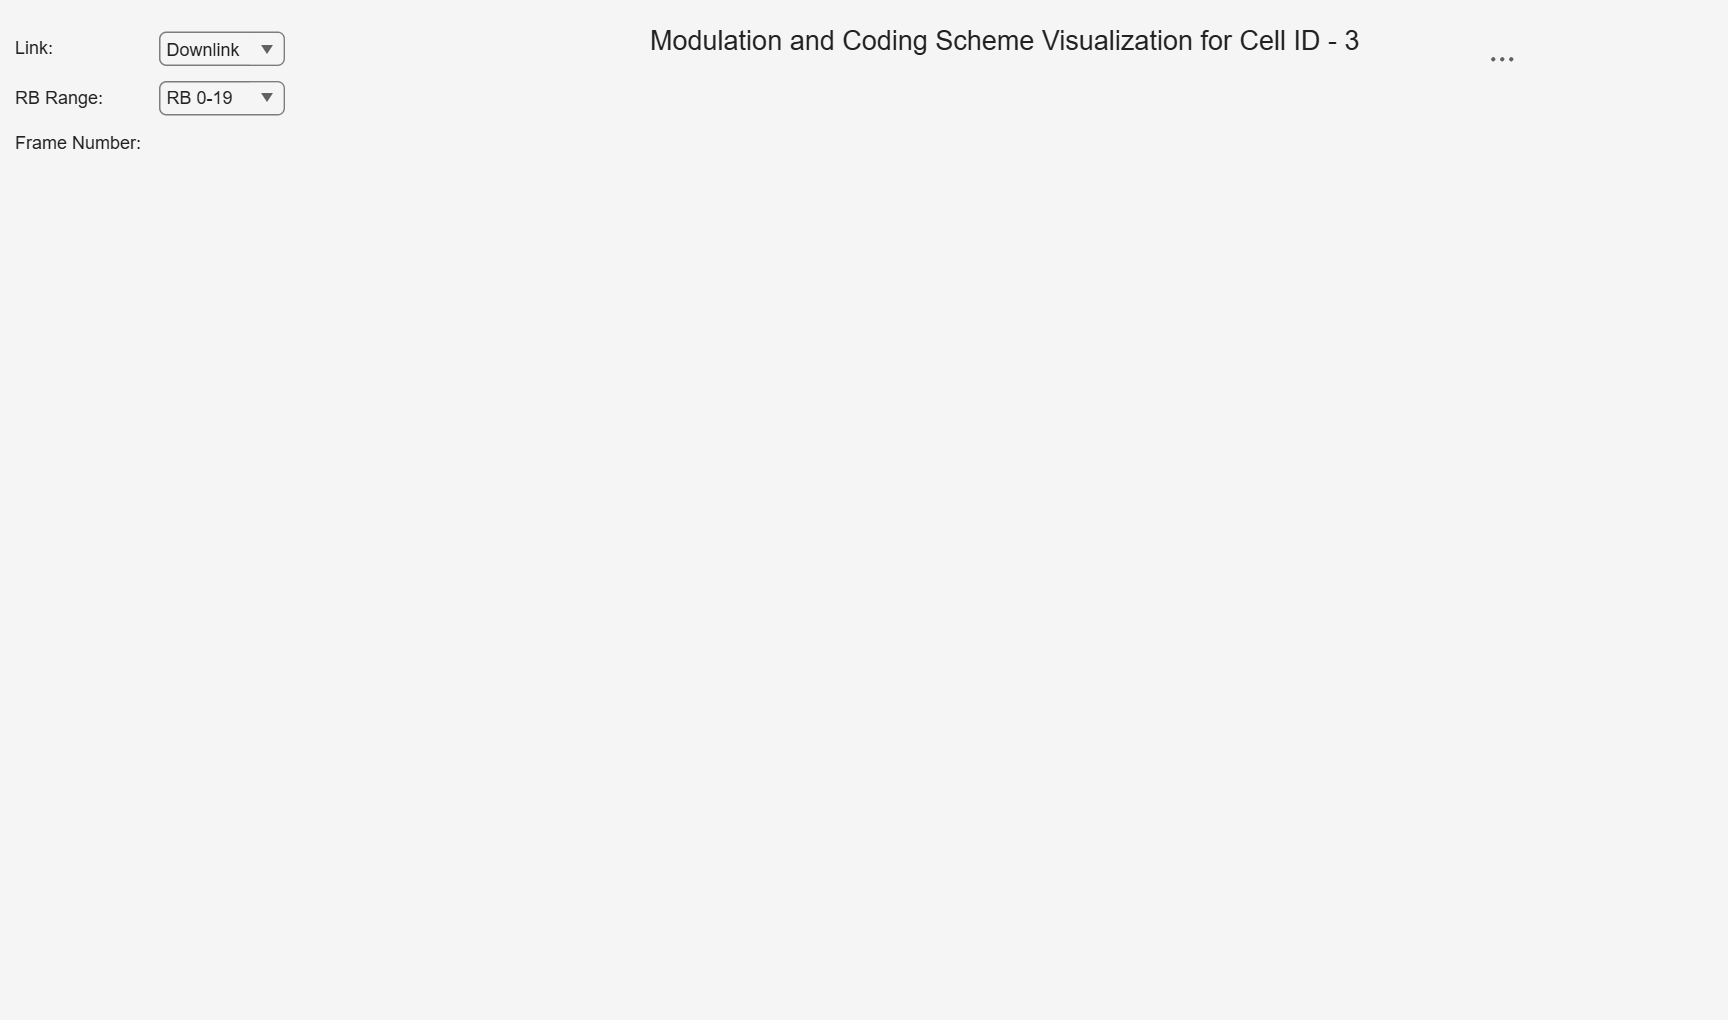

gridVisualizer = helperNRGridVisualizer(numFrameSimulation,gNBs(cellofInterest),UEs, ResourceGridVisualization=false,SchedulingLogger= simSchedulingLogger,MCSGridVisualization=true,CellOfInterest=cellofInterest);

metricsVisualizer = helperNRMetricsVisualizer(gNBs(cellofInterest),UEs,CellOfInterest=cellofInterest,RefreshRate=100,PlotSchedulerMetrics=true,PlotPhyMetrics=false,LinkDirection="DL");

# Task 4/4: Run the Simulation 

Runs the discrete-event simulator in MATLAB to execute the network model.

**Instructions to complete the task**

Use addNodes() function to add Bluetooth LE nodes to the network simulator   

Type `doc wirelessnetworksimulator.run` in the MATLAB Command Window, and see the "Syntax" section.

Note : use the following values as arguments 

- networkSimulator

- simulationTime

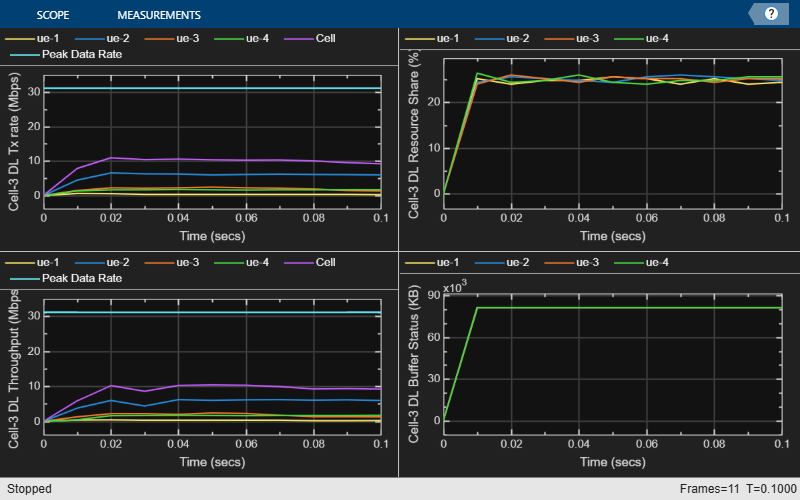

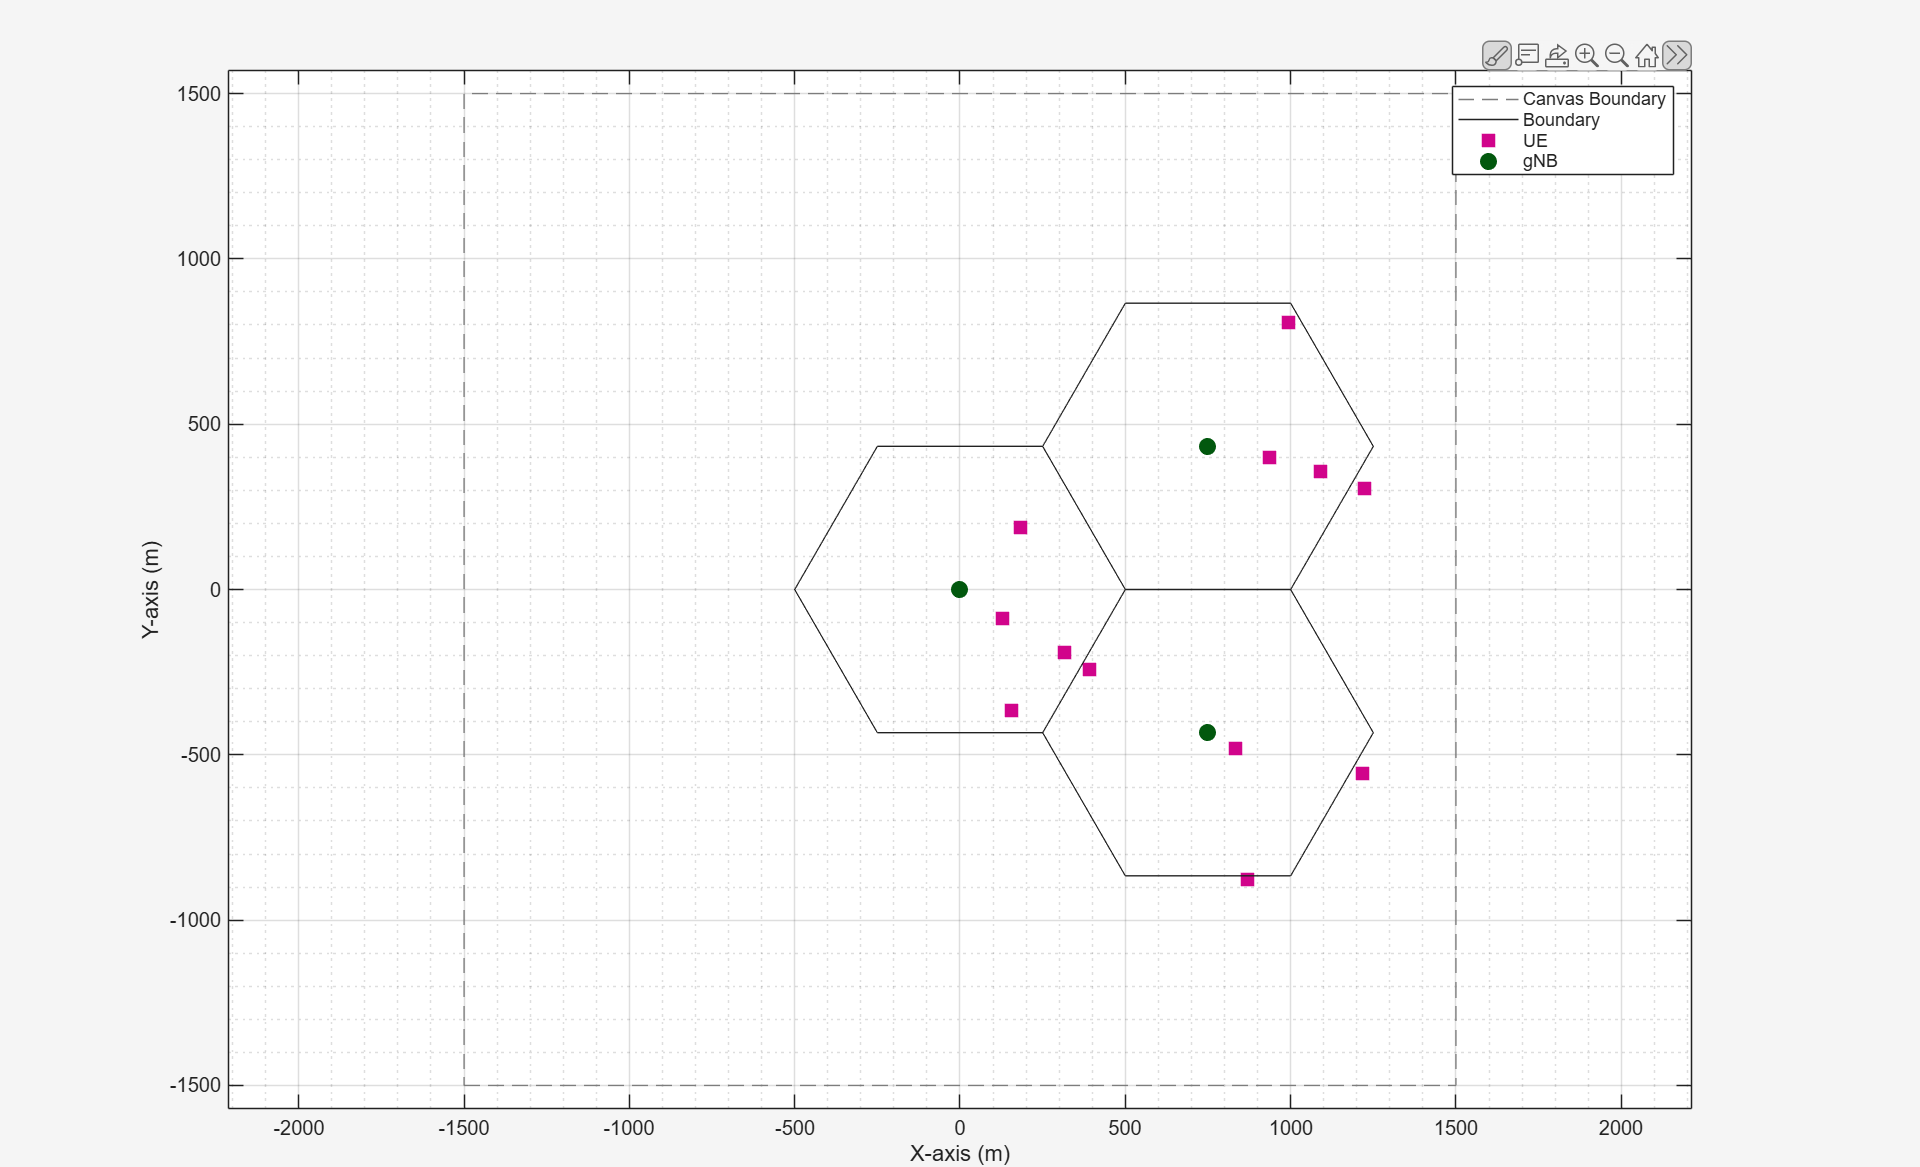

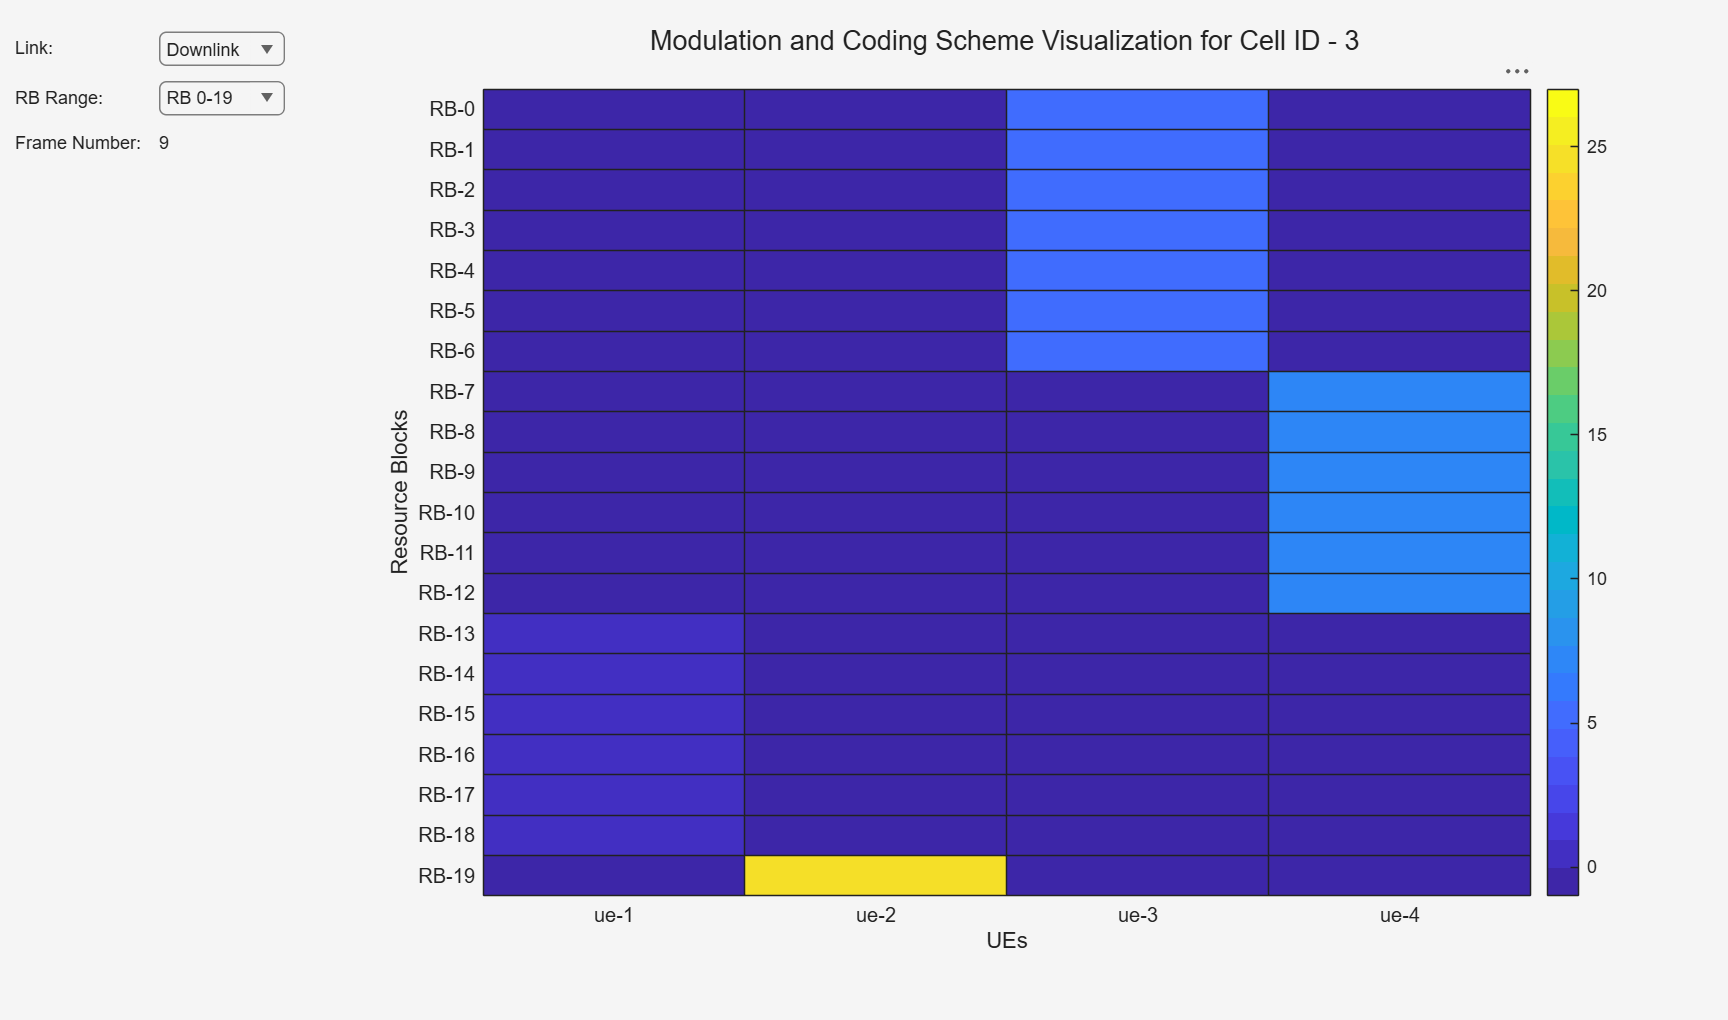

% <enter code below>
run(networkSimulator, simulationTime);

displayPerformanceIndicators(metricsVisualizer)

Peak DL throughput: 31.11 Mbps
Achieved cell DL throughput: 9.31 Mbps
Achieved DL throughput for each UE: [0.31        5.67        1.79        1.54]
Peak DL spectral efficiency: 6.22 bits/s/Hz
Achieved DL spectral efficiency for cell: 1.86 bits/s/Hz
Block error rate for each UE in the DL direction: [0.121        0.04       0.071        0.04]



path(p);

*Copyright 2025-2026 The MathWorks, Inc.*